clear all

## Function List (Order: Base to Top)

% function [Na, Na_X, J_cauchy] = Finite_Derivative(nodel_position,cauchy_position)
% ----Which evaluate the quadrilateral element's shape function, the derivative of shape function, 
% ----and Jacobi matrix of mapping

% function f_body = Force_Body(X)
% ----Which evaluate the body force term: f(x,y)=2*\pi^2*sin(\pi*x)*sin(\pi*y)

% function U_Exact=Get_U_Exact(X)
% ----Which evaluate the theoratical solution U: U(x,y)=sin(\pi*X(1))*sin(\pi*X(2))

% function D_U_Exact=Get_D_U_Exact(X)
% ----Which evaluate the gradiant of the theoratical solution U:
% ----GradU(x,y)=[\pi*cos(pi*X(1))*sin(pi*X(2)) \pi*sin(pi*X(1))*cos(pi*X(2))] 

% function [K_Element, F_Element] = Stiffness_Element(X)
% ----Which call "function Finite_Derivative" and "function Force_Body" in order to evaluate the
% ----element's stiffness matrix and body force vector

% function [K_Global, Internal_F_Global]=Stiffness_Global(Table, Global_X)
% ----Which call "function Stiffness_Element" in order to create the
% ----global stiffness matrix and body force vector

% function [Global_X, Table, Boundary_H_List, Boundary_Q_List] = Get_Mesh(n_x,n_y)
% ----Which generate the mesh associate with its points/table of element, the Q boundary (natural), 
% ----and the H boundary (essential) of this problem (homogeneous H boundary only)

% function U=Solver(Global_X, Table, Boundary_H_List, Boundary_Q_List)
% ----Call all the functions above to solve the problem

% function [Error_Element, Error_Element_1] = Get_Error_Element(X, U_FEM_Element)
% ----Which evaluate the L2 error of the element

% function [Error_Global, Error_Global_1] = Get_Error_Global(Global_X, Table, U_FEM)
% ----Which evaluate the L2 error of the domain


## Problem 2

n_x=3;
n_y=2;

Map=zeros(n_y+1,n_x+1);
for i=1:n_y+1
    for j=1:n_x+1
        Map(i,j)=(i-1)*(n_x+1)+j;
    end
end

[Global_X, Table, Boundary_H_List, Boundary_Q_List] = Get_Mesh(n_x,n_y);

% Mesh Visualization
Map

Map =      1     2     3     4
     5     6     7     8
     9    10    11    12


% Node Data (row#: nodal id, col#: coordinate, entities: value)
Global_X

Global_X =          0         0
    0.6667         0
    1.3333         0
    2.0000         0
         0    0.5000
    0.6667    0.5000
    1.3333    0.5000
    2.0000    0.5000
         0    1.0000
    0.6667    1.0000


% Table of Element (row#: element's id, col#: nodal order, entities: nodal id)
Table

Table =      1     2     6     5
     2     3     7     6
     3     4     8     7
     5     6    10     9
     6     7    11    10
     7     8    12    11


## Problem 3

% H Boundary List (Homogeneous)
Boundary_H_List

Boundary_H_List =      1     2     3     4     5     8     9    10    11    12


% Q Boundary List (Homogeneour)
Boundary_Q_List

Boundary_Q_List =      6     7


## Problem 4

[K_Global, Internal_F_Global]=Stiffness_Global(Table, Global_X);
% Global Stiffness Matrix
K_Global

K_Global =     0.6944   -0.0278         0         0   -0.3194   -0.3472         0         0         0         0         0         0
   -0.0278    1.3889   -0.0278         0   -0.3472   -0.6389   -0.3472         0         0         0         0         0
         0   -0.0278    1.3889   -0.0278         0   -0.3472   -0.6389   -0.3472         0         0         0         0
         0         0   -0.0278    0.6944         0         0   -0.3472   -0.3194         0         0         0         0
   -0.3194   -0.3472         0         0    1.3889   -0.0556         0         0   -0.3194   -0.3472         0         0
   -0.3472   -0.6389   -0.3472         0   -0.0556    2.7778   -0.0556         0   -0.3472   -0.6389   -0.3472         0
         0   -0.3472   -0.6389   -0.3472         0   -0.0556    2.7778   -0.0556         0   -0.3472   -0.6389   -0.3472
         0         0   -0.3472   -0.3194         0         0   -0.0556    1.3889         0         0   -0.3472   -0.3194
         0         0 

% Global Force Vector (Count For Body Force Only)
Internal_F_Global

Internal_F_Global =     0.4121
    0.9053
   -0.9053
   -0.4121
    1.4695
    3.2283
   -3.2283
   -1.4695
    0.4121
    0.9053


## Problem 5

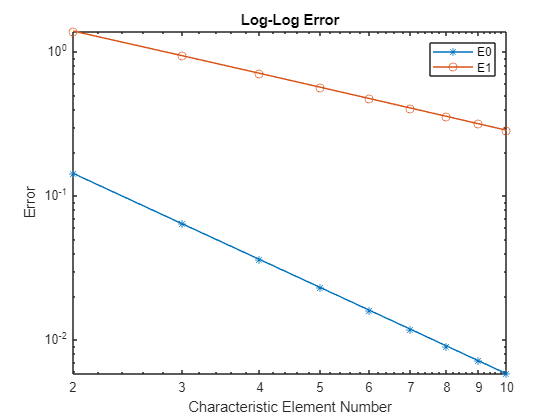

n_List=2:1:10;
Error_List=zeros(length(n_List),1);
Error_List_1=zeros(length(n_List),1);

for n_id=1:length(n_List)
% Set up Problem
n=n_List(n_id);
n_x=2*n;
n_y=n;

Map=zeros(n_y+1,n_x+1);
for i=1:n_y+1
    for j=1:n_x+1
        Map(i,j)=(i-1)*(n_x+1)+j;
    end
end

Map;

% Generate Mesh

[Global_X, Table, Boundary_H_List, Boundary_Q_List] = Get_Mesh(n_x,n_y);

Global_X;
Table;

[K_Global, Internal_F_Global]=Stiffness_Global(Table, Global_X);

% Solver
U_FEM=Solver(Global_X, Table, Boundary_H_List, Boundary_Q_List);

n_total=(n_x+1)*(n_y+1);
U_Exact=zeros(n_total,1);
for i=1:n_total
    U_Exact(i)=Get_U_Exact(Global_X(i,:));
end

[Error_Global, Error_Global_1] = Get_Error_Global(Global_X, Table, U_FEM); % L2 Error

Error_List(n_id)=Error_Global;
Error_List_1(n_id)=Error_Global_1;
end

loglog(n_List,Error_List,'*-')
hold on
loglog(n_List,Error_List_1,'o-')
xlabel('Characteristic Element Number')
ylabel('Error')
legend('E0','E1')
title('Log-Log Error')

## Problem 6 

% See Below:

function [Error_Global, Error_Global_1] = Get_Error_Global(Global_X, Table, U_FEM)

Error_Global=0;
Error_Global_1=0;

for i=1:size(Table,1)
    Element_X=Global_X(Table(i,:),:)'; % Transfer from different data structure
    U_FEM_Element=U_FEM(Table(i,:));
    [Error_Element, Error_Element_1] = Get_Error_Element(Element_X, U_FEM_Element);
    Error_Global=Error_Global+Error_Element;
    Error_Global_1=Error_Global_1+Error_Element_1;
end
Error_Global=sqrt(Error_Global);
Error_Global_1=sqrt(Error_Global_1);
end

function [Error_Element, Error_Element_1] = Get_Error_Element(X, U_FEM_Element)

 Gauss_Cauchy=[-sqrt(1/3) sqrt(1/3)];
 Gauss_Weight=[1 1];

 % X=[0 2 2 0;0 0 2 2]; x1 x2 x3 x4 y1 y2 y3 y4

Sum_L2=0;
Sum_L2_1=0;
for index_cauchy=1:2
    for index_yita=1:2
        % F=J*[Na_x Na_y]*[K]*[Nb_x,Nb,y]'
        % N_X*K*N_X'

        Cauchy=[Gauss_Cauchy(index_cauchy);Gauss_Cauchy(index_yita)];

        nodel_position=X';
        cauchy_position=Cauchy;

        [Na, Na_X, J_cauchy] = Finite_Derivative(nodel_position,cauchy_position);
%
        U_Exact_Point=Get_U_Exact(nodel_position'*Na);
        U_FEM_Point=U_FEM_Element'*Na;
        F_L2=J_cauchy*(U_FEM_Point-U_Exact_Point)^2;
        Inc_L2=F_L2*Gauss_Weight(index_cauchy)*Gauss_Weight(index_yita);
        Sum_L2=Sum_L2+Inc_L2;
%
        D_U_Exact_Point=Get_D_U_Exact(nodel_position'*Na);
        D_U_FEM_Point=U_FEM_Element'*Na_X;
        F_L2_1=J_cauchy*norm(D_U_FEM_Point-D_U_Exact_Point)^2;
        Inc_L2_1=F_L2_1*Gauss_Weight(index_cauchy)*Gauss_Weight(index_yita);
        Sum_L2_1=Sum_L2_1+Inc_L2_1;
    end
end

Error_Element = Sum_L2;
Error_Element_1 = Sum_L2_1;

end

function D_U_Exact=Get_D_U_Exact(X)
    D_U_Exact=[pi*cos(pi*X(1))*sin(pi*X(2)) pi*sin(pi*X(1))*cos(pi*X(2))];
end


function U_Exact=Get_U_Exact(X)
    U_Exact=sin(pi*X(1))*sin(pi*X(2));
end

function U=Solver(Global_X, Table, Boundary_H_List, Boundary_Q_List)
[K_Global, Internal_F_Global]=Stiffness_Global(Table, Global_X);

Number_of_Q=length(Boundary_Q_List);
Number_of_H=length(Boundary_H_List);

Boundary_H_Value=zeros(1,Number_of_H); % Assume homogeneous H boundary

% Boundary_Q_Value=[0 0 0 0]; not build in

K_QQ=zeros(Number_of_Q,Number_of_Q);
K_QH=zeros(Number_of_Q,Number_of_H);
F_Q=zeros(Number_of_Q,1);

for i=1:Number_of_Q
    for j=1:Number_of_Q
        K_QQ(i,j)=K_Global(Boundary_Q_List(i),Boundary_Q_List(j));
    end
    F_Q(i)=Internal_F_Global(Boundary_Q_List(i));

    for k=1:Number_of_H
        K_QH(i,k)=K_Global(Boundary_Q_List(i),Boundary_H_List(k));
    end
end

U_Q=K_QQ\(F_Q-K_QH*Boundary_H_Value');

U=zeros(Number_of_Q+Number_of_H,1);

for i=1:Number_of_Q
    U(Boundary_Q_List(i))=U_Q(i);
end
for i=1:Number_of_H
    U(Boundary_H_List(i))=Boundary_H_Value(i);
end

end


function [Global_X, Table, Boundary_H_List, Boundary_Q_List] = Get_Mesh(n_x,n_y)
% Only support rectangular grid for [0 2]x[0 1]
n_total=(n_x+1)*(n_y+1);
n_h=2*(n_x+n_y+1);
n_q=n_total-n_h;

% Generate Global_X (node position)
Global_X = zeros(n_total,2);

Boundary_H_List=[];
Boundary_Q_List=[];

dx=2/n_x;
dy=1/n_y;
for i=1:n_y+1
    for j=1:n_x+1
        X_id=(n_x+1)*(i-1)+j;
        Global_X(X_id,1)=(j-1)*dx;
        Global_X(X_id,2)=(i-1)*dy;

        if (i==1||i==n_y+1)||(j==1||j==n_x+1)
            Boundary_H_List=[Boundary_H_List X_id];
        else
            Boundary_Q_List=[Boundary_Q_List X_id];
        end

    end
end

% Generate Table of Element
Table = zeros(n_x*n_y,4);
for i=1:n_y
    for j=1:n_x
        Table_id=n_x*(i-1)+j;
        X_id=(n_x+1)*(i-1)+j;
        Table(Table_id,:)=[X_id X_id+1 X_id+n_x+2 X_id+n_x+1];
    end
end

end


function [K_Global, Internal_F_Global]=Stiffness_Global(Table, Global_X)
    
    n=size(Global_X,1);
    K_Global=zeros(n,n);
    Internal_F_Global=zeros(n,1);

    for i=1:size(Table,1)
        
        X=zeros(2,4);
        for j=1:4
            X(:,j)=Global_X(Table(i,j),:)';
        end

        [K_Element, F_Element] = Stiffness_Element(X);

        for a=1:4
            for b=1:4
                K_Global(Table(i,a),Table(i,b))=K_Global(Table(i,a),Table(i,b))+K_Element(a,b);
            end
            Internal_F_Global(Table(i,a))=Internal_F_Global(Table(i,a))+F_Element(a);
        end

        % Internal_F_Element=Interal_Force_Element(X);
        % 
        % for a=1:4
        %     Internal_F_Global(Table(i,a))=Internal_F_Element(Table(i,a));
        % end

    end
end

% X=[0 2 2 0;0 0 2 2]
% [K_Element, F_Element] = Stiffness_Element(X)

function [K_Element, F_Element] = Stiffness_Element(X)
K=eye(2);

 Gauss_Cauchy=[-sqrt(1/3) sqrt(1/3)];
 Gauss_Weight=[1 1];

 % X=[0 2 2 0;0 0 2 2]; x1 x2 x3 x4 y1 y2 y3 y4

Sum=0;
Sum_F=0;
for index_cauchy=1:2
    for index_yita=1:2
        % F=J*[Na_x Na_y]*[K]*[Nb_x,Nb,y]'
        % N_X*K*N_X'

        Cauchy=[Gauss_Cauchy(index_cauchy);Gauss_Cauchy(index_yita)];
%
        nodel_position=X';
        cauchy_position=Cauchy;
%
        [Na, Na_X, J_cauchy] = Finite_Derivative(nodel_position,cauchy_position);

        F = J_cauchy*Na_X*K*Na_X';
        
        Inc = F*Gauss_Weight(index_cauchy)*Gauss_Weight(index_yita);
        
        Sum = Sum+Inc;

        f_body = Force_Body(nodel_position'*Na);

        F_F = J_cauchy*f_body*Na;

        Inc_F = F_F*Gauss_Weight(index_cauchy)*Gauss_Weight(index_yita);

        Sum_F = Sum_F+Inc_F;
    end
end

K_Element = Sum;
F_Element = Sum_F;

end

function f_body = Force_Body(X)
x=X(1);
y=X(2);
f_body=2*pi^2*sin(pi*x)*sin(pi*y);
end

function [Na, Na_X, J_cauchy] = Finite_Derivative(nodel_position,cauchy_position)

% Evaluate integral point location
cau = cauchy_position(1);
yi = cauchy_position(2);

% Evaluate Na,cauchy
cauchy_table = [-1 -1;1 -1;1 1;-1 1];

Na = zeros(4,1);
Na_cauchy = zeros(4,2); % nen number of element nodal = 4
for i=1:4
    cauchy = cauchy_table(i,1);
    yita = cauchy_table(i,2);
    Na(i)=0.25*(1+cau*cauchy)*(1+yi*yita);
    Na_cauchy(i,1) = 0.25*cauchy*(1+yi*yita);
    Na_cauchy(i,2) = 0.25*yita*(1+cau*cauchy);
end

% Evaluate X,cauchy
X_cauchy = nodel_position'*Na_cauchy;

% Evaluate J_cauchy
J_cauchy = det(X_cauchy);

% Evaluate Na,X
Na_X = Na_cauchy*[X_cauchy(2,2) -X_cauchy(1,2); -X_cauchy(2,1) X_cauchy(1,1)]/J_cauchy;

end
